## **CYKLY UHELNÝCH TEPELNÝCH ELEKTRÁREN - SUPERKRITICkÝ RANKIN-CLAUSIŮV**

**prof. Ing. Josef STETINA, Ph.D. / Vysoké učení technické v Brně**

**email: josef.stetina@vutbr.cz**

** www: **[http://termomechanika.online/](http://termomechanika.online/)

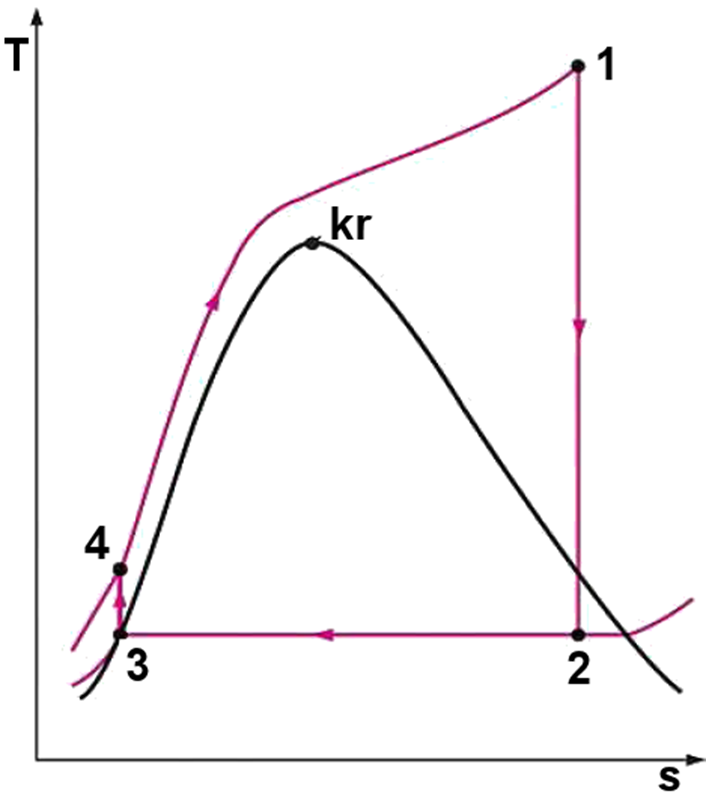

**Moderní parní zařízení pracují s tlaky v nadkritické oblasti p > 22,06 ****MPa****.**

**Teplota**** p****řehřáté**** páry 580 ****°****C až 600 ****°****C**

**U ****ultrakritických**** až 700 ****°****C**

Mají termickou účinnost přes 40 % pro fosilní paliva.

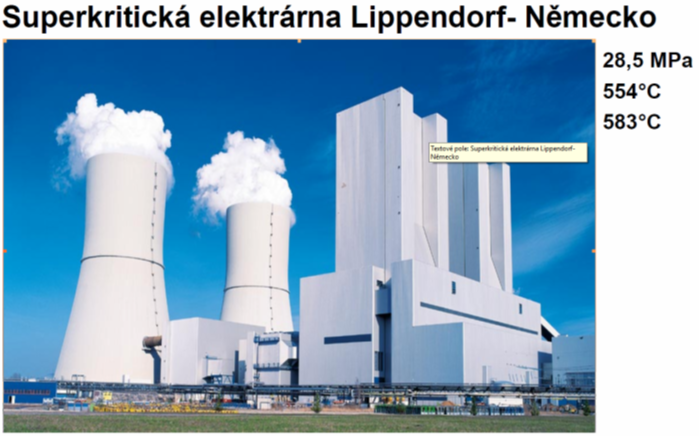

Pro teploty do 560 °C se používají klasické feritické oceli, pro teploty nad 560 °C je zapotřebí použít austenitické oceli nebo superslitiny - **nárůst ceny****.**

Přivdené měrné teplo            $\[{q_H} = {h_1} - {h_4}\]$

Odvedené měrné teplo        $\[{q_C} = {h_3} - {h_2}\]$

Měrná práce turbíny            $\[{a_T} = {h_1} - {h_2}\]$

Měrná práce napájecího čerpadla            $\[{a_N} = h_3 - h_4 = v \cdot ({p_3} - {p_4})\]$

Termická účinnost                $
\[{\eta _t} = \frac{{{a_T} - \left| {{a_N}} \right|}}{{{q_H}}} = \frac{{{a_O}}}{{{q_H}}} = \frac{{({h_1} - {h_2}) + \left( {{h_3} - {h_4}} \right)}}{{{h_1} - {h_4}}}\]$

Výkon elektrárny                   $$P = \dot m a_o =  \dot m \left(a_T - \left|a_N\right| \right)$$

### **Typy elektráren**

**Subcritical**

12 – 20 MPa     510 – 560 °C

**Critical**

23 – 25 MPa     510 – 560 °C

**Supercritical**

25 – 36 MPa     580 – 600 °C

**Ultra-****supercritical**

25 – 36 MPa     600 – 700 °C

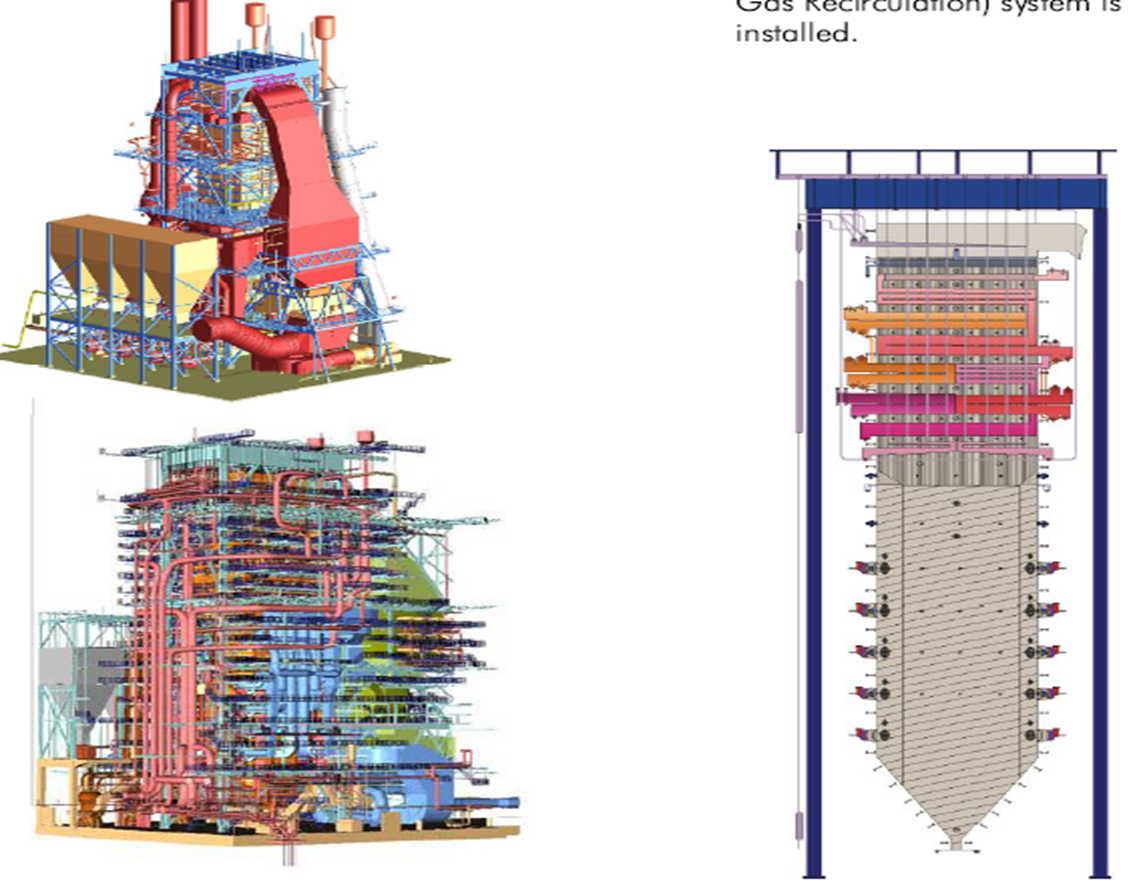

### Příklad 

Uhelná tepelná elektrárna pacuje podle super kritického Rankin-Clausiova cyklu s přehřevem páry. Maximální tlak a teplota páry v přehříváku jsou 24 MPa a 680 °C. Tlak v kondenzátoru je 0.05 MPa. Napájecí čerpladlo dodává do kotle 50 kg/s vody. Určete přivedené a odvedené teplo, termickou účinnost a výkon bloku. Zakreslete cyklus v T-s diagramu.

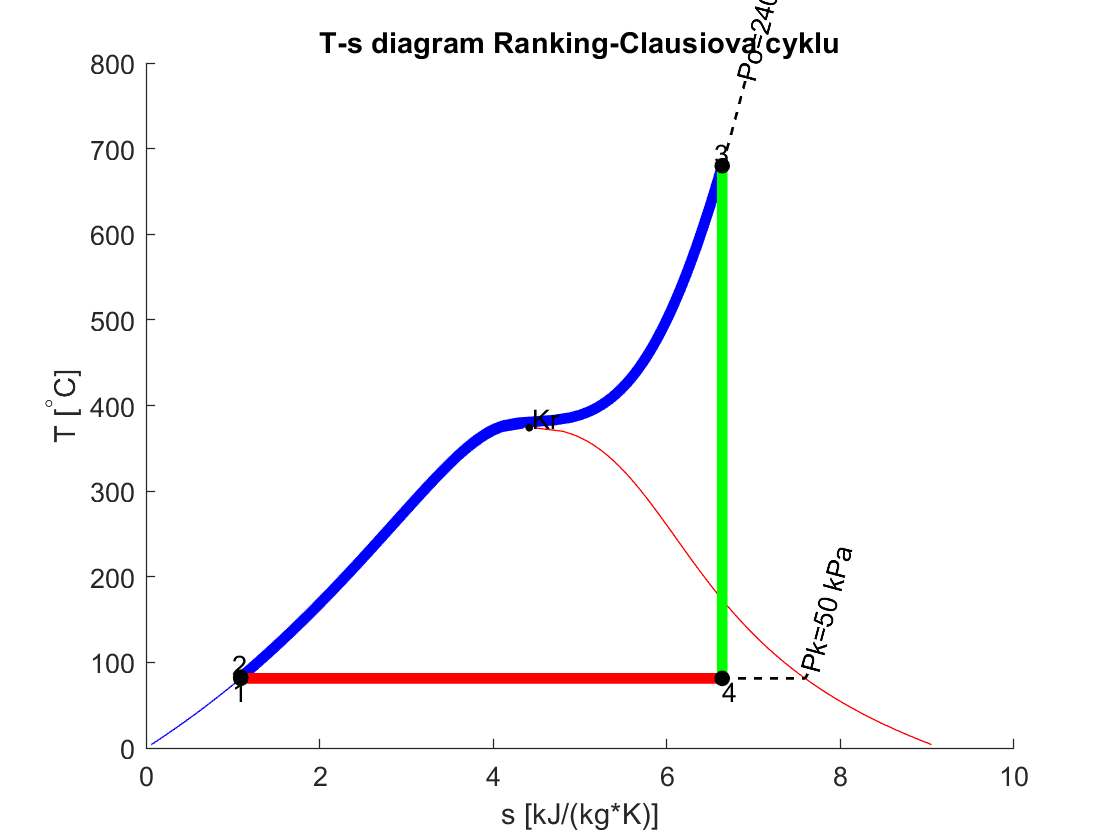

mh = 50;           % kg/s
pmaxMPa = 24.0;    % MPa
pminMPa = 0.05;    % MPa
tmaxC = 680;       % °C

%% Výpočet
p=[0,0,0,0];
t=[0,0,0,0];
s=[0,0,0,0];
h=[0,0,0,0];
p(2)=pmaxMPa;   % input('Zadej tlak ohřevu [MPa]:');
p(1)=pminMPa;   % input('Zadej tlak kondenzace [MPa]:');
t(3)=tmaxC;     % input('Zadej maximalni teplotu páry na vstupu do turbíny [C]:');
p=10*p;
p(3)=p(2);
p(4)=p(1);

% určení neznámých veličin
t(1)=XSteam('Tsat_p',p(1));
s(1)=XSteam('sL_p',p(1));
h(1)=XSteam('hL_p',p(1));
s(2)=s(1);
t(2)=XSteam('T_ps',p(2),s(2));
s(3)=XSteam('s_pT',p(3),t(3));
s(4)=s(3);
h(4)=XSteam('h_ps',p(4),s(3));
h(3)=XSteam('h_pT',p(3),t(3));
t(4)=XSteam('T_ph',p(4),h(4));
h(2)=XSteam('h_ps',p(2),s(1));

% měrná práce turbíny
at=h(3)-h(4);
Pt = at * mh;

% měrná práce napáječky
an=h(2)-h(1);
Pn = an * mh;

% měrná práce cyklu
a0=at-an;
P = a0 * mh;

% přivedené teplo
qh=h(3)-h(2);
Qh = qh * mh;

% odvedené teplo
qc=h(1)-h(4);
Qc = qc * mh;

% termická účinnost oběhu
n=abs(a0)/qh;

% vykreslení grafu
figure;
hold on;

% vykreslení čar syté kapaliny a páry
vekT = linspace(0,800,200);
svyp = arrayfun(@(x) XSteam('sV_T',x),vekT);
skap = arrayfun(@(x) XSteam('sL_T',x),vekT);
plot(svyp,vekT,'r-')
plot(skap,vekT,'b-')

% vykreslení jednotlivých dějů
plot([s(1) s(2)],[t(1) t(2)],'y-','linewidth',4)

t23=linspace(t(2),t(3),200);
s23 = arrayfun(@(t) XSteam('s_PT',p(2),t),t23);
plot(s23,t23,'b-','linewidth',4)

plot([s(3) s(4)],[t(3) t(4)],'g-','linewidth',4)

s41 = linspace(s(4),s(1),200); 
t41 = arrayfun(@(x) XSteam('T_ps',p(1),x),s41);
plot(s41,t41,'r-','linewidth',4);

% úpravy grafu
i=[0,0];
i(1)=max(skap);
i(2)=min(svyp);
l=mean(i);

plot(l,374.1,'k.','MarkerSize',10);
text(l+0.03,385,'Kr');
vekToh=linspace(t(3),t(3)+100,100);
soh = arrayfun(@(x) XSteam('s_PT',p(2),x),vekToh);
plot(soh,vekToh,'k--','linewidth',1);
text(soh(end),vekToh(end),sprintf('Po=%1.0f kPa',p(3)*100),'rotation',75)

vekskon=linspace(s(4),s(4)+1,100);
vekTkon = arrayfun(@(x) XSteam('T_ps',p(1),x),vekskon);
plot(vekskon,vekTkon,'k--','linewidth',1);
text(vekskon(end),vekTkon(end),sprintf('Pk=%1.0f kPa',p(4)*100),'rotation',75)

plot(s,t,'k.','MarkerSize',20);

text(s(1)-0.1,t(1)-15,'1');
text(s(2)-0.1,t(2)+15,'2');
text(s(3)-0.1,t(3)+15,'3');
text(s(4),t(4)-15,'4');

% název grafu a popisy os
title('T-s diagram Ranking-Clausiova cyklu')
xlabel('s [kJ/(kg*K)]')
ylabel('T [^\circC]')

Výstupní data

fprintf('Měrná práce turbíny:   %.3f kJ/kg\n',at);

Měrná práce turbíny:   1421.606 kJ/kg


fprintf('Měrná práce napáječky: %.3f kJ/kg\n',an);

Měrná práce napáječky: 24.556 kJ/kg


fprintf('Měrné přivedené teplo: %.3f kJ/kg\n',qh);

Měrné přivedené teplo: 3363.333 kJ/kg


fprintf('Měrné odvedené teplo:  %.3f kJ/kg\n',qc);

Měrné odvedené teplo:  -1966.284 kJ/kg


fprintf('Měrná práce cyklu:     %.3f kJ/kg\n',a0);

Měrná práce cyklu:     1397.050 kJ/kg


fprintf('Výkon turbíny:         %.1f MW\n',Pt/1000.0);

Výkon turbíny:         71.1 MW


fprintf('Příkon napáječky:      %.1f MW\n',Pn/1000.0);

Příkon napáječky:      1.2 MW


fprintf('Přivedený tepelný tok: %.1f MW\n',Qh/1000.0);

Přivedený tepelný tok: 168.2 MW


fprintf('Odvedený tepelný tok:  %.1f MW\n',Qc/1000.0);

Odvedený tepelný tok:  -98.3 MW


fprintf('Výkon bloku/cyklu:     %.1f MW\n',P/1000.0);

Výkon bloku/cyklu:     69.9 MW


fprintf('Termická účinnost cyklu: %1.1f%%\n',abs(n)*100);

Termická účinnost cyklu: 41.5%
